% folder_name = 'truncated_2'

folder_name = 'truncated_2'

% 
% p = 'orig';
% file = strcat('data\', folder_name, '\',p,'Pc.csv')
% table = readtable(file);
% 
% % table = sortrows(table,1);
% 
% x = table.Var1;
% y = table.Var2;
% z = table.Var3;
% u = table.Var4;
% v = table.Var5;
% w = table.Var6;

filename = 'C:\Users\pyeung\Downloads\HighwayLong3.csv_10.10.10.143_17037.csv';
T = readtable(filename, 'PreserveVariableNames', true);

x = T.("x (m)");
y = T.("y (m)");
z = T.("z (m)");

x = x(z<1);
y = y(z<1);
z = z(z<1);

intens = T.intensity;
intens = intens(z<1);
xyz = [x, y, z];

% writematrix(xyz,strcat('data\',save_folder,'coordinates.csv'))
pc = pointCloud(xyz, 'Intensity', intens(z<=1));

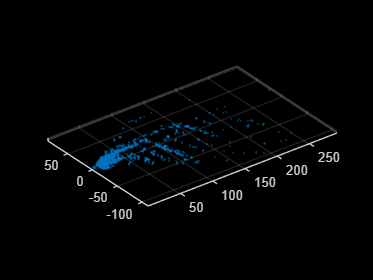

% Create a point cloud object with the location and intensity data.
% Notice that imsegkmeans supports inputs of type uint8, uint16, int8,
% int16 and single.
ptCloud = pointCloud(xyz, "Intensity", uint8(intens));
% Segment based on intensity values.
numClusters = 3;
labels = imsegkmeans(ptCloud.Intensity, numClusters);
% Select each cluster and store it in a pointCloud object.
ptCloudArr = pc.empty(0, numClusters);
for i = 1:numClusters
    ptCloudArr(i) = select(pc, labels == i);
end
% Optional: you can also visualize each cluster as follows.
colorsPlot = lines(numClusters);
for k = 1:numClusters
    pcshow(ptCloudArr(k).Location, colorsPlot(k,:))
    hold on
end